**Results of offline version on S1 and S2 datasets, as shown in Figure 6(a) and 6(c) of the paper.**

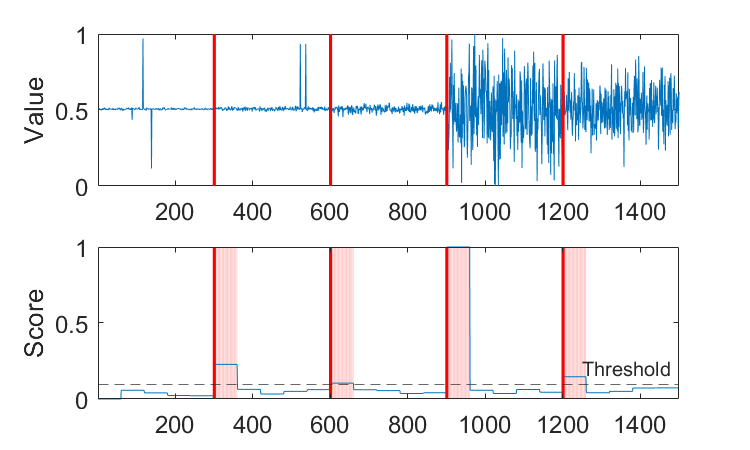

clear
load('S1.mat')
win_size = 60;
a = 0;

rng(3)
[best_Pscore, ~, ~ ] = best_psi(Y, win_size);
[b_threshold, result] = best_threshold(best_Pscore, a);

figure('Position',[100 100 500 300])

co=[0.00,0.45,0.74];
subplot(2, 1, 1)
plot(Y)
hold on
bar(L, 'red','BarWidth',8)
xlim([1 length(best_Pscore)])
ylabel('Value')

set(gcf,'color','w');
set(gca,'LooseInset',get(gca,'TightInset'))
set(gca,'FontSize',12);
set(gcf,'color','w');

subplot(2, 1, 2)
bar(result, 'red','FaceAlpha',0.2)
hold on
plot(best_Pscore, 'Color',co)
hold on
bar(L, 'red','BarWidth',8)
xlim([1 length(best_Pscore)])
yline(b_threshold, '--','Threshold')
ylabel('Score')
 
set(gcf,'color','w');
set(gca,'FontSize',12);

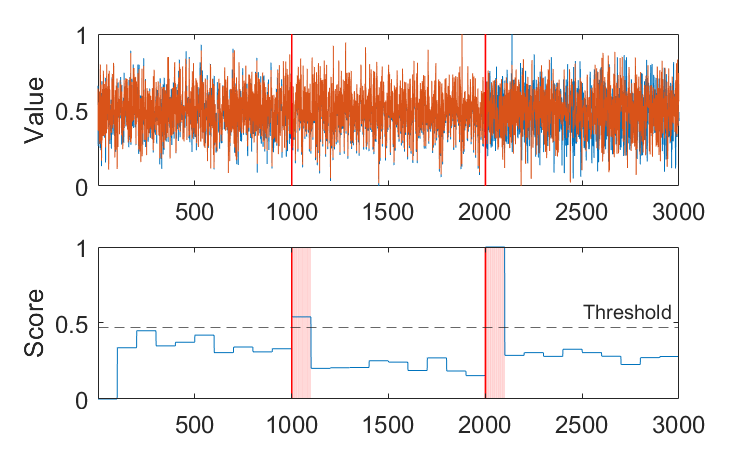

clear
load('S2.mat')
win_size = 100;
a = 1;

[best_Pscore, ~, ~ ] = best_psi(Y, win_size);
[b_threshold, result] = best_threshold(best_Pscore, a);

figure('Position',[100 100 500 300])

co=[0.00,0.45,0.74];
subplot(2, 1, 1)
plot(Y)
hold on
bar(L, 'red','BarWidth',8)
xlim([1 length(best_Pscore)])
ylabel('Value')

set(gcf,'color','w');
set(gca,'LooseInset',get(gca,'TightInset'))
set(gca,'FontSize',12);
set(gcf,'color','w');

subplot(2, 1, 2)
bar(result, 'red','FaceAlpha',0.2)
hold on
plot(best_Pscore, 'Color',co)
hold on
bar(L, 'red','BarWidth',8)
xlim([1 length(best_Pscore)])
yline(b_threshold, '--','Threshold')
ylabel('Score')
 
set(gcf,'color','w');
set(gca,'FontSize',12);

**Results of online version on S1 and S2 datasets, as shown in Figure 8 of the paper.**

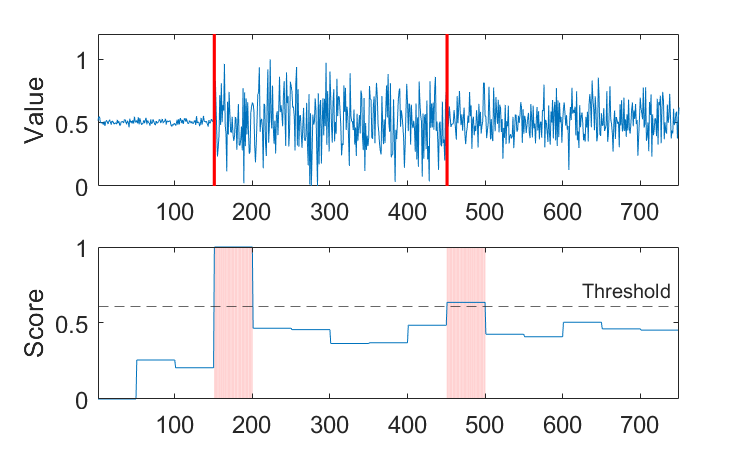

clear
load('S1.mat')
ratio = 0.5;
win_size = 50;
a = 0;

[trainset, testset, ~, testlabel] = datasetsplit(Y, L, ratio);
[best_Pscore, ~, b_psi ] = best_psi(trainset, win_size);
[b_threshold, ~] = best_threshold(best_Pscore, a);
best_test_score = point_score(testset, b_psi, win_size);

result = best_test_score-best_test_score;
for i = 1:length(best_test_score)
    if b_threshold < best_test_score(i)
        result(i) = 1;
    else
        result(i) = 0;
    end
end

figure('Position',[100 100 500 300])
subplot(2, 1, 1)
plot(testset)
hold on
bar(testlabel*3, 'red','BarWidth',4)


xlim([1 length(best_test_score)])
ylabel('Value')
ylim([0 1.2])
set(gcf,'color','w');
set(gca,'LooseInset',get(gca,'TightInset'))
set(gca,'FontSize',12);
set(gcf,'color','w');

co=[0.00,0.45,0.74];

subplot(2, 1, 2)
bar(result, 'red','FaceAlpha',0.2,'EdgeColor','none')
hold on
plot(best_test_score, 'Color',co)
xlim([1 length(best_test_score)])
yline(b_threshold, '--','Threshold')
ylabel('Score') 
set(gcf,'color','w');
set(gca,'LooseInset',get(gca,'TightInset'))
set(gca,'FontSize',12);

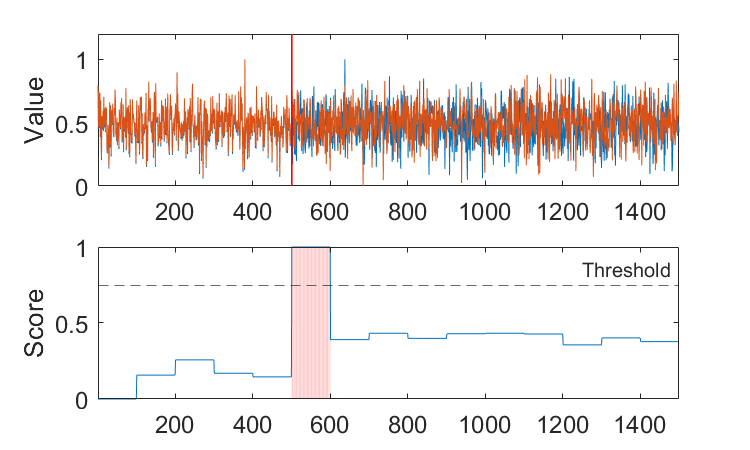

clear
load('S2.mat')
ratio = 0.5;
win_size = 100;
a = 1;

[trainset, testset, trainlabel, testlabel] = datasetsplit(Y, L, ratio);
[best_Pscore, best_ent, b_psi ] = best_psi(trainset, win_size);
[b_threshold, ~] = best_threshold(best_Pscore, a);
best_test_score = point_score(testset, b_psi, win_size);

result = best_test_score-best_test_score;
for i = 1:length(best_test_score)
    if b_threshold < best_test_score(i)
        result(i) = 1;
    else
        result(i) = 0;
    end
end

figure('Position',[100 100 500 300])
subplot(2, 1, 1)
plot(testset)
hold on
bar(testlabel*3, 'red','BarWidth',4)


xlim([1 length(best_test_score)])
ylabel('Value')
ylim([0 1.2])
set(gcf,'color','w');
set(gca,'LooseInset',get(gca,'TightInset'))
set(gca,'FontSize',12);
set(gcf,'color','w');

co=[0.00,0.45,0.74];

subplot(2, 1, 2)
bar(result, 'red','FaceAlpha',0.2,'EdgeColor','none')
hold on
plot(best_test_score, 'Color',co)
xlim([1 length(best_test_score)])
yline(b_threshold, '--','Threshold')
ylabel('Score') 
set(gcf,'color','w');
set(gca,'LooseInset',get(gca,'TightInset'))
set(gca,'FontSize',12);